% intialisation
clc
clear
load('tut_meshes.mat') % load in meshes

t = optode.tAxis; % time axis
Nt = numel(t);
f = optode.fAxis; % freq axis

% define gaussian time gates as our gating function
gateSize = 200e-12/(2*sqrt(2*log(2)));
gateStart = 0.3e-9;
gatePeriod = 6.5e-9;
gates = zeros(round(gatePeriod/gateSize),length(t));
for i = 1:size(gates,1)
    gates(i,:) = exp(-(t-(gateStart+(i-1).*gateSize)).^2./(2.*gateSize.^2));
end

g_t = gateStart:gateSize:(gateStart+gatePeriod); % gate mid points
gates_fc = td2fc(gates,f,t,2); % Fourier coefficients of gates


## Generate ground truth data

Add absorbing inclusion to mesh

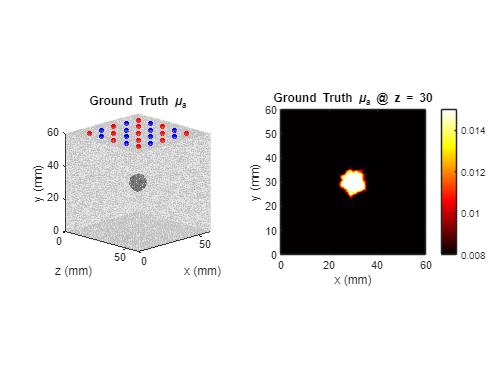

% Add inclusion
incl = [30 30 30 5];
idx = (mesh.node(:,1) - incl(1)).^2 + (mesh.node(:,2) - incl(2)).^2 + (mesh.node(:,3) - incl(3)).^2 < incl(4)^2;
muaGT = mesh.mua;
muaGT(idx) = 0.015;
mesh = update_properties(mesh,[muaGT mesh.musp]);

% Plot
figure
tl = tiledlayout(1,2);
nexttile
hold on
plotdmesh_snd(mesh,0.1,false)
plotfun_vol(mesh,mesh.mua)
title('Ground Truth \mu_a')
view(45,16)
nexttile
plotfun_slice(mesh,mesh.mua,hot,'z=30')
title('Ground Truth \mu_a @ z = 30')
colorbar

drawnow

Generate boundary data with absorbing inclusion

[~,data_gt] = flu_solve(mesh);


solving for fluence...done!
detection generated!


data_gt = fc2tg(data_gt,gates_fc,f,Nt,2); % Time gated

## Generate data from homogenous reconstruction mesh

Generate boundary data on with homogenous optical properties, along with sensitivitiy and residual

[J,data_r] = J_complex(mesh_r); % sensitivity and boundary data


solving for adjoint fluence...done!

solving for fluence...done!
detection generated!

generating complex absorption jacobian...done!


data_r = fc2tg(data_r,gates_fc,f,Nt,2); % Time gated
J = fc2tg(J,gates_fc,f,Nt,2)./data_r; % Time gated
err = log(data_gt) - log(data_r); % residual

% flatten
err = err(:);
J = reshape(J,[],size(J,3));

## Sensitivity reshape by weighting

We can solve for weightings to reshape the sensitivty to a given sensitvity

% array of gaussian spots at 3 depths
[X,Y,Z] = meshgrid(30,[50 35 20],30);
pos_s = sortrows([X(:) Y(:) Z(:)],2,"descend");
Js = target_spots(mesh_r,pos_s,1.5,'gauss');

% index for data above > 1%
id = id_thresh(data_gt,'all');

% solve for weighting at different regularisations
lam_s = [1e-4 1e-6 1e-8];
w = zeros(size(pos_s,1),sum(id(:)),3);
w_plot = zeros(size(data_r,2),3);
for i = 1:size(w,3)
    w(:,:,i) = reshape_J(J(id(:),:),Js,lam_s(i));
    temp = zeros(size(data_r));
    temp(id(:)) = w(2,:,i);
    w_plot(:,i) = temp(67,:).'; 
end
% weight and reshape sensitvity
wJ = pagemtimes(w,J(id(:),:));

Note the worsening of spot quality with increase in depth and regulariser

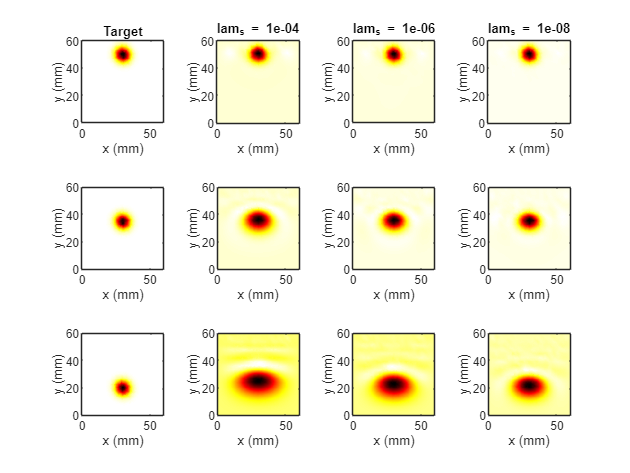

% plot weighted sensitivity vs target
figure
tiledlayout(3,4)
for i = 1:size(pos_s,1)
    nexttile
    plotfun_slice(mesh_r,mesh_r.g2m*Js(i,:).',hot,'z=30')
    if i == 1
        title('Target')
    end
    for ii = 1:size(w,3)
        nexttile
        plotfun_slice(mesh_r,mesh_r.g2m*wJ(i,:,ii).',hot,'z=30')
        if i == 1
            title(sprintf('lam_s = %1.0e',[lam_s(ii)]))
        end
    end
end

Note that the weighting contrast increases for small regularisation, what does this mean for noisy measurements?

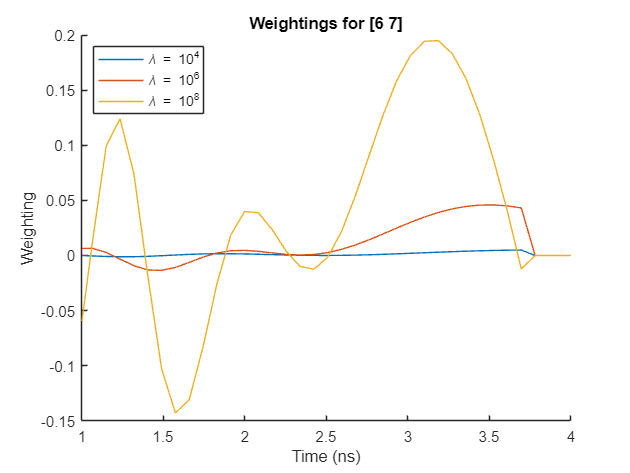

% plot weightings for one channel
figure
hold on 
plot(g_t.*1e9,w_plot)
legend('\lambda = 10^4','\lambda = 10^6','\lambda = 10^8','Location','northwest')
xlim([1 4])
xlabel('Time (ns)')
ylabel('Weighting')
title('Weightings for [6 7]')

## Localise inclusion with reshaped sensitvity

Using the corect weighting we can see the residual is strongest when the reshaped sensitvitiy overlaps with the inclusion

NOTE: Due to boundary node mismatch is it is critical to remove early gate measurements as they strongly interact with the boundary. Otherwise residual is biased to surface

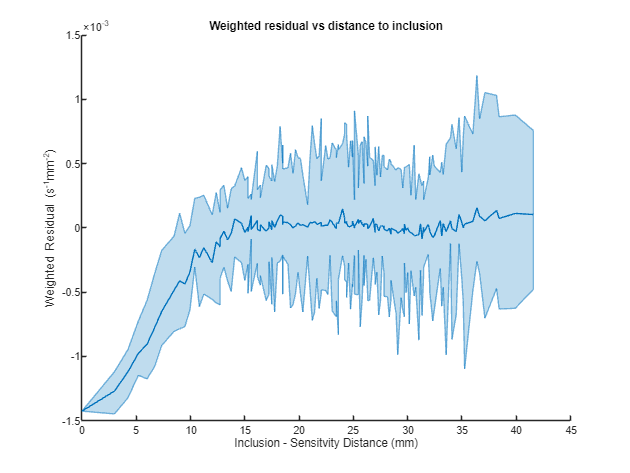

% solve weightings for gaussian spots
% define gaussian spots
ds = 3;
ds = 2*ds:ds:max(mesh_r.node(:,1)-2*ds);
[X,Y,Z] = ndgrid(ds,ds,ds);
pos_s = [X(:) Y(:) Z(:)];

lam_s = 1e-6; % regulariser

% index for data above > 1% and <= 80% on the falling edge IMPORTANT
id = id_thresh(data_gt,0.8); 

Js = target_spots(mesh_r,pos_s,1.5,'gauss');
w = reshape_J(J(id(:),:),Js,lam_s);

% weight error
wErr = w*err(id(:));
% sort by distance and find mean, max and min for each distance
dist = vecnorm(pos_s-incl(:,1:3),2,2);
[dist,idx] = sort(dist,1);
[dist,~,ic] = unique(dist);
wErr_sort = accumarray(ic,wErr(idx),[],@mean);
max_err = accumarray(ic,wErr(idx),[],@max);
min_err = accumarray(ic,wErr(idx),[],@min);

% Remap error to sensitivity position
[~,id_n] = ismember(pos_s,mesh_r.grid,"rows");
wErr_node = zeros(size(mesh_r.grid,1),size(wErr,2));
wErr_node(id_n,:) = wErr;
wErr_node = mesh_r.g2m*wErr_node;

figure
hold on
clr = colororder;
plot(dist,wErr_sort,'-','Color',clr(1,:))
min_max = [min_err; flip(max_err)];
patch([dist; flip(dist)], min_max,clr(1,:),'FaceAlpha',0.25,'EdgeColor',clr(1,:),'EdgeAlpha',0.5)
set(gca,'FontSize',7,'FontUnits','points')
xlabel('Inclusion - Sensitvity Distance (mm)')
ylabel('Weighted Residual (s^{-1}mm^{-2})')
title('Weighted residual vs distance to inclusion')

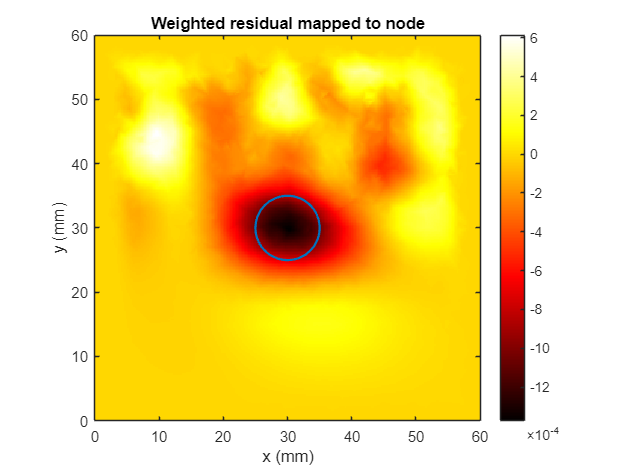


figure
plotfun_slice(mesh_r,wErr_node,hot,'z=30',incl)
colorbar
title('Weighted residual mapped to node')

## Weighted LM reconstruction

Reconstruction of optical properties from surface measurements, uses time gated data-types

clearvars -except mesh_r muaGT mesh data_gt gates

% interpolate ground truth to recon mesh for plotting
muaGT_r = mesh2mesh(mesh_r,muaGT,mesh.node,mesh.elem);

% define J_s spots on grid half steps (found empirically to work well)
ds = mesh_r.dxyz;
[X,Y,Z] = meshgrid((ds*1.5):ds:(max(mesh_r.node(:,1)-(ds*1.5))),...
    (max(mesh_r.node(:,1)-(ds*1.5))):-ds:(ds*1.5),...
    (ds*1.5):ds:(max(mesh_r.node(:,1)-(ds*1.5))));
pos_s = sortrows([X(:) Y(:) Z(:)],[],'ascend'); 

% reconstruct absorption
new_mu = wghtd_LM_recon(mesh_r,data_gt,gates,pos_s,[1e2 1e-6]);


============= iteration 0 =============
generating forward data and jacobian... done!
weighting jacobian and residuals...done!
error: 2.016%

============= iteration 1 =============
lambda: 1.00e+02
solving for optical property update...done!
optical properties updated
generating forward data and jacobian... done!
weighting jacobian and residuals...done!
error: 1.873%
error change: -0.143%

============= iteration 2 =============
lambda: 5.62e+01
solving for optical property update...done!
optical properties updated
generating forward data and jacobian... done!
weighting jacobian and residuals...done!
error: 1.726%
error change: -0.147%

============= iteration 3 =============
lambda: 3.16e+01
solving for optical property update...done!
optical properties updated
generating forward data and jacobian... done!
weighting jacobian and residuals...done!
error: 1.600%
error change: -0.126%

============= iteration 4 =============
lambda: 1.78e+01
solv

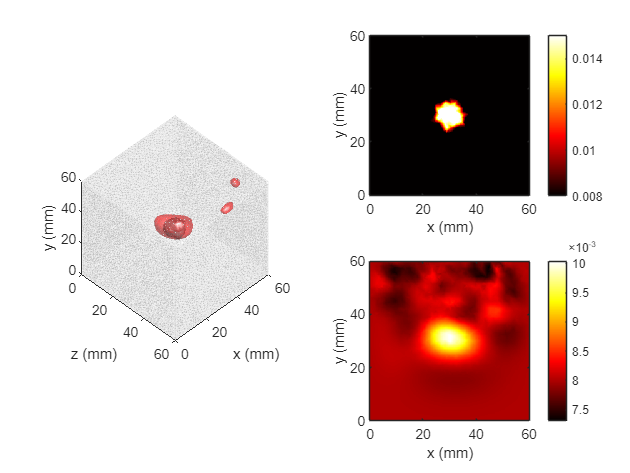


figure
tiledlayout(2,2)
nexttile([2 1])
plotfun_vol(mesh_r,muaGT_r,new_mu)

nexttile
plotfun_slice(mesh_r,muaGT_r,hot,'z=30')
colorbar

nexttile
plotfun_slice(mesh_r,new_mu,hot,'z=30')
colorbar